# MODELO DE DIAGNÓSTICO

close all; clc; clearvars;

rng(432); % seed for reproducibility

## PREPROCESAMIENTO DE LA TABLA

T = readtable('Caracteristicas_MODELO.csv')

T = 1379×12 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    C_DRatio    glaucoma
    __________________    ___________    ___________    ___________    __________    __________________    __________________    _________    _________________    _________________    ________    ________

    {'image_0001.jpg'}      3.5854         6.2108          4.642       1.9289e+05           975.1                633.81           4565.9           727.79          

% filas_a_eliminar = T.C_DRatio == 0;
numeros_a_eliminar = {'0002','0003','0004','0026','0027','0028','0036','0037','0043','0057','0060','0062','0071','0075','0076','0080','0097','0122','0125','0137','0135','0152','0168','0173','0180','0197','0198','0213','0214','0216','0217','0219','0221','0237','0238','0256','0257','0269','0273','0289','0298','0306','0316','0319','0332','0334','0339','0340','0348','0351','0383','0389','0399','0422','0425','0438','0450','0473','0482','0496','0504','0518','0522','0561','0572','0590','0594','0595','0600','0613','0633','0636','0645','0671','0675','0708','0715','0742','0753','0759','0778','0779','0781','0783','0791','0792','0795','0800','0807','0816','0822','0827','0829','0830','0832','0842','0852','0869','0902','0904','0905','0913','0922','0925','0926','0927','0937','0938','0941','0950','0961','0969','0972','0977','0979','0989','0990','0991','1002','1027','1041','1045','1053','1061','1075','1076','1080','1082','1084','1088','1100','1105','1117','1133','1152','1151','1163','1164','1169','1174','1175','1191','1193','1200','1206','1208','1223','1232','1244','1251','1254','1263','1266','1268','1269','1270','1277','1288','1300','1305','1306','1307','1309','1314','1318','1330','1332','1340','1345','1350','1352','1356','1360','1372','1374','1378','1381','1382','1390','1391','1402','1406','1420','1427','1430','1443','1446','1455','1465','1466','1475','1502','1503','1507','1535','1532','1542','1545','1551','1561','1564','1567','0265','0755','0862','0976','1020','1098','1317','1482','1537','1568'};

ans = 212

Pocertaje_eliminado=round(size(numeros_a_eliminar,2)*100/height(T))

Pocertaje_eliminado = 15

% Paso 3: Convertir los números al formato de nombres de imágenes en la tabla
nombres_a_eliminar = strcat('image_', numeros_a_eliminar, '.jpg');

% Paso 4: Convertir cada nombre de imagen en una celda de cadena individual
nombres_a_eliminar = cellstr(nombres_a_eliminar);

% Paso 5: Encontrar las filas que contienen los nombres de imágenes a eliminar
filas_a_eliminar = ismember(T.image, nombres_a_eliminar);

% Paso 6: Eliminar las filas
T(filas_a_eliminar, :) = [];

% Paso 7: Guardar la tabla actualizada si es necesario
writetable(T, 'Caracteristicas_MODELO_actualizado.csv');


T=readtable("Caracteristicas_MODELO_actualizado.csv")

T = 1167×12 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    C_DRatio    glaucoma
    __________________    ___________    ___________    ___________    __________    __________________    __________________    _________    _________________    _________________    ________    ________

    {'image_0001.jpg'}      3.5854         6.2108          4.642       1.9289e+05           975.1                633.81           4565.9           727.79          

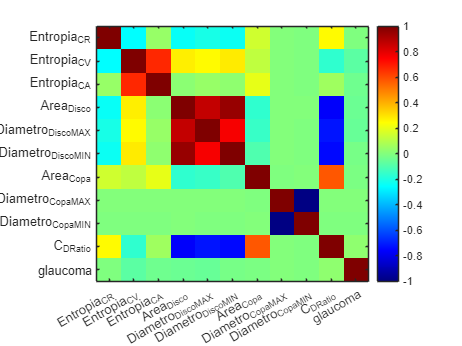

X = T{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values
variables = T.Properties.VariableNames;
figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:,2:end));
yticks(1:30);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;

T.glaucoma = cellstr(num2str(T.glaucoma));

for i = 1:height(T)
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No glaucoma';
    end
end


X = T{:, 2:end-1};
Y = T.glaucoma;

### **Desbalance de la variable glaucoma**

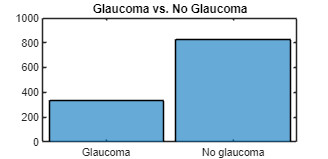

figure('Position', [0 0 350 170]);
histogram(categorical(Y))
title('Glaucoma vs. No Glaucoma')


class_no_glaucoma = T(T.glaucoma == "No glaucoma", :); % Clase mayoritaria
class_glaucoma = T(T.glaucoma == "Glaucoma", :); % Clase minoritaria

num_class_glaucoma = height(class_glaucoma); % Número de muestras en la clase minoritaria
random_indices = randperm(height(class_no_glaucoma), num_class_glaucoma); % Índices aleatorios
class_no_glaucoma_downsampled = class_no_glaucoma(random_indices, :); % Submuestrear la clase mayoritaria

% Guardar los índices de las filas eliminadas
indices_eliminados = setdiff(1:height(class_no_glaucoma), random_indices);
% Guardar los índices eliminados en un archivo CSV para referencia
writematrix(indices_eliminados', 'indices_eliminados.csv');

% Paso 5: Combinar las clases
balanced_data = [class_no_glaucoma_downsampled; class_glaucoma];
balanced_data = balanced_data(randperm(height(balanced_data)), :); % Mezclar aleatoriamente

% Paso 6: Verificar el balance de clases después del submuestreo
disp('Número de muestras de cada clase (balanceado):');

Número de muestras de cada clase (balanceado):


disp(['Glaucoma: ', num2str(sum(balanced_data.glaucoma == "Glaucoma"))]);

Glaucoma: 337


disp(['No glaucoma: ', num2str(sum(balanced_data.glaucoma == "No glaucoma"))]);

No glaucoma: 337



prueba=sortrows(balanced_data.image(balanced_data.glaucoma=="Glaucoma"))

prueba = 337×1 cell array
    {'image_0005.jpg'}
    {'image_0010.jpg'}
    {'image_0016.jpg'}
    {'image_0029.jpg'}
    {'image_0032.jpg'}
    {'image_0034.jpg'}
    {'image_0044.jpg'}
    {'image_0047.jpg'}
    {'image_0051.jpg'}
    {'image_0058.jpg'}
    {'image_0059.jpg'}
    {'image_0070.jpg'}
    {'image_0072.jpg'}
    {'image_0079.jpg'}
    {'image_0084.jpg'}
    {'image_0086.jpg'}
    {'image_0090.jpg'}
    {'image_0091.jpg'}
    {'image_0092.jpg'}
    {'image_0093.jpg'}
    {'image_0102.jpg'}
    {'image_0103.jpg'}
    {'image_0106.jpg'}
    {'image_0107.jpg'}
    {'image_0110.jpg'}
    {'image_0119.jpg'}
    {'image_0121.jpg'}
    {'image_0128.jpg'}
    {'image_0141.jpg'}
    {'image_0146.jpg'}



X = balanced_data{:, 2:end-1}; % Características (ajusta según las columnas de tus datos)
Y = balanced_data.glaucoma; % Etiquetas

cv = cvpartition(Y, 'HoldOut', 0.4, 'Stratify', true);

X_train = X(cv.training, :);
X_test  = X(cv.test, :);
Y_train = Y(cv.training);
Y_test  = Y(cv.test);

### ENTRENAMIENTO MODELO KNN

We can train our first KNN model simply as:

mdl = fitcknn(X_train, Y_train, 'NumNeighbors', 3);

Evaluate now the performance on the training data

Y_pred = predict(mdl, X_train);

acc_train = sum(strcmp(Y_pred, Y_train)) / length(Y_train)

acc_train = 0.7531

### **Test**

[Y_pred, scores] = predict(mdl, X_test);

We may also want to check first the accuracy of the model as well as the AUC. 

acc_test = sum(strcmp(Y_pred, Y_test)) / length(Y_test)

acc_test = 0.4647

[~, ~, ~, auc_test] = perfcurve(Y_test, scores(:,1), 'No glaucoma')

auc_test = 0.5162

A Confusion Chart will allow us to visualize the amount of predictions that were done for any of the true classes and identify any possible biases that our model may have:

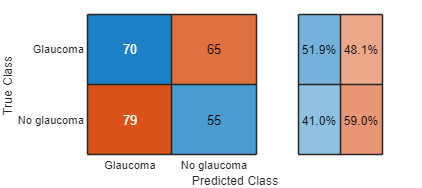

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized')

### O**ptimización- KNN**

cv_in = cvpartition(Y_train, 'KFold', 10, 'Stratify', true);
opt.CVPartition = cv_in;
opt.Verbose     = 0;     % [0, 1, 2] to control messages displayed
opt.ShowPlots   = false; % to control visualization

mdl_opt = fitcknn(X_train, Y_train, 'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opt);
best_values = mdl_opt.HyperparameterOptimizationResults.bestPoint

best_values = 1×3 table
    NumNeighbors    Distance     Standardize
    ____________    _________    ___________

         4          chebychev       true    


n_neighbors = best_values.NumNeighbors;
distance    = string(best_values.Distance);
standardize = best_values.Standardize == 'true';

mdl_final = fitcknn(X_train, Y_train, 'NumNeighbors', n_neighbors, 'Distance', distance, 'Standardize', standardize);

[Y_pred, scores] = predict(mdl_final, X_test);

### Test tras o**ptimización**

acc_test_opt = sum(strcmp(Y_pred, Y_test)) / length(Y_test)

acc_test_opt = 0.5204

[~, ~, ~, auc_test_opt] = perfcurve(Y_test, scores(:,1), 'No glaucoma')

auc_test_opt = 0.5031

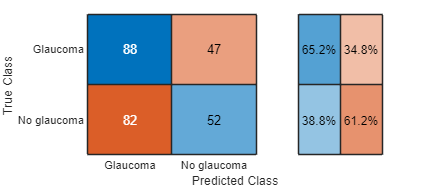


figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');


sensitivity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(Y_test, 'No glaucoma')) / sum(strcmp(Y_test, 'No glaucoma'));
specificity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(Y_test, 'Glaucoma')) / sum(strcmp(Y_test, 'Glaucoma'));

balanced_accuracy = (sensitivity + specificity) / 2

balanced_accuracy = 0.5200

Additionally, an in-depth analysis of the missclassified cases can be done. This can give an insight on how to apply further imrovements to the model:

test_rows = find(cv.test);
misclassified_rows = test_rows(~strcmp(Y_test, Y_pred));
T(misclassified_rows, :)

ans = 129×12 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    C_DRatio       glaucoma    
    __________________    ___________    ___________    ___________    __________    __________________    __________________    _________    _________________    _________________    ________    _______________

    {'image_0007.jpg'}      3.5516         6.1004         4.2818       1.5301e+05          840.98                616.42            18090           7